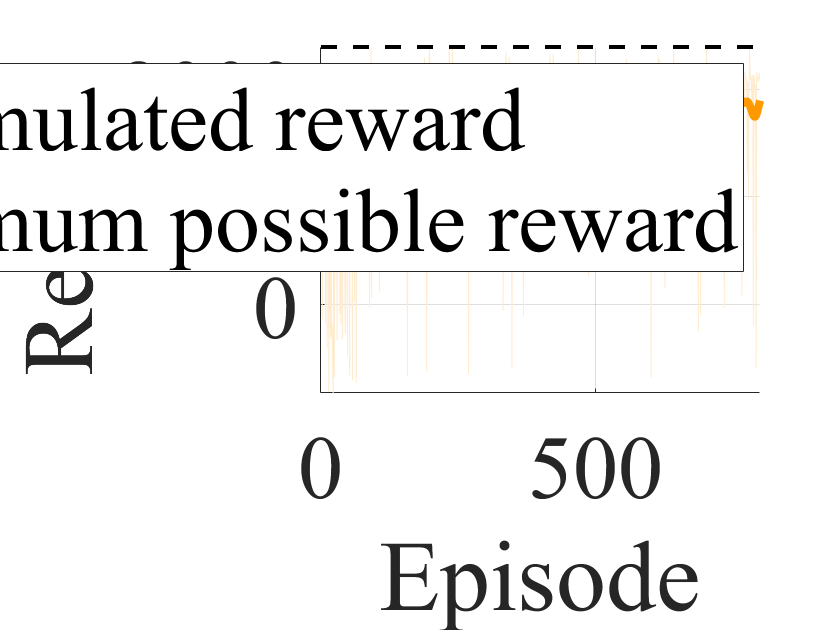

reward = zeros(1,800);
% reward_biaozhun = (61*60/2+500)/60
load('data13.mat')
target = zeros(1,800);
target(1,:)=2391;

for i = 1:800
    reward(i) = sum(episode_reward{1,i});
end
episode = 1:800;
reward_s = smoothdata(reward,'gaussian',30);

reward(93)=2391;
reward(199)=2391;
reward(235)=2391;
reward(241)=2391;
reward(703)=2391;

% reward = zeros(1,50);
% % reward_biaozhun = (61*60/2+500)/60
% for i = 1:50
%     reward(i) = mean(episode_reward{1,i});
% end
% episode = 1:50;
% reward_s = smoothdata(reward,'gaussian',15);

% episode_conf = [episode episode(end:-1:1)];
% reward_conf = [reward_s+7 reward_s(end:-1:1)-7];
figure(1);
% p=fill(episode_conf,reward_conf,'blue');
% p.FaceColor= [1,0.8,0.8]
% p.EdgeColor = 'none'
% hold on 




% plot(reward(1:50),'k','linewidth',4,'Color','#FF9900')%美化后的图像绘制
hold on;grid on;
plot(episode,reward,'Color','#FFEBCD');hold on;grid on;
plot(reward_s(1:800),'k','linewidth',4,'Color','#FF9900')%美化后的图像绘制
plot(episode,target,'--','Color','k','linewidth',2);hold on;
set(gca,'FontName','Times New Roman','FontSize',45);

% set(gca,'FontSize',30);


hl21 = xlabel('Episode','FontName','Times New Roman','FontSize',50);
% set(hl21,'interpreter','latex')
hl22 = ylabel('Reward','FontName','Times New Roman','FontSize',50,'Rotation',90);
% set(hl22,'interpreter','latex')

hl20 = legend('','Accumulated reward','Maximum possible reward','FontName','Times New Roman','FontSize',45);
set(hl20,'Box','on');
set(gca,'ytick',[-3000 -2000 -1000 0 1000 2000  3000]);

% hl20 = legend('$$reward$$','FontSize',15);
% set(hl20,'Box','off');
% set(hl20,'interpreter','latex')



